# PROYECTO 2: OPTIMIZACIÓN CON RESTRICCIONES

# MÉTODO SIMPLEX MATRICIAL

## EQUIPO N°1

- Mariana Zapata Covarrubias 195111

- Mauricio Verduzco Chavira 195106

- Ricardo Illescas Carrancá 197809

- Alejandro Terrazas Maeshiro 187977

## IDENTIFICACIÓN DEL PROBLEMA Y REQUERIMIENTOS

### Identificación del problema

El objetivo de este proyecto es programar de manera eficiente el método simplex y aplicar la función correspondiente a problemas de programación lineal.

Para lograr esto, se programó un algoritmo en MatLab que podrá resolver cualquier problema de programación lineal.

### Requerimientos

- El programa debe resolver problemas de maximización y minimización de programación lineal.

- La programación debe hacer uso de la función LU y evitar el uso de la matriz inversa de B.

- La función debe enviar un error si la solución no está acotada y reconocer la existencia de múltiples soluciones.

- El script que llame a la función deberá resolver varios problemas sencillos, incluyendo uno de minimización transformado usando el problema dual.

## MODELO MATEMÁTICO

El código debe ser capaz de resolver problemas de este tipo: 


$$\begin{array}{l}
\max \;z=c^{\prime } x\to \textrm{Definir}\;\textrm{maximización}\;o\;\textrm{minimización}\;y\;\textrm{función}\;\textrm{objetivo}\;\;\\
\textrm{sujeto}\;a:\to \;\textrm{Definir}\;\textrm{restricciones}\\
\textrm{Ax}=b\\
b\ge 0\\
x\ge 0
\end{array}$$


Esta es la estructura general para representar los problemas en el método simplex. 

### Algoritmo Simplex

El método simplex es una manera de resolver problemas de optimización por medio de programación lineal usando elementos adicionales (restricciones). La mayoría de los problemas lineales se pueden resolver con aplicaciones como MatLab o Lingo, pero el método Simplex es un algoritmo que puede ser calculado a mano. Este método es el que usualmente está detrás de las soluciones de las aplicaciones mencionadas. Para resolver un modelo de programación lineal usando el algoritmo Simplex se utiliza el siguiente método:

- Trabajar con una forma estándar.

- Agregar variables de holgura (cuando la restricción es mayor o igual) y/o de exceso (si la restricción es menor o igual).

- Crear una matriz compuesta por los elementos necesarios para ejecutar las operaciones que hacen funcional al algoritmo.

- Variables pivote.

- Hacer los cambios correspondientes.

- Checar la optimalidad.

- Identificar los valores óptimos.

Todo esto se tomó en cuenta para hacer el programa utilizando MatLab.

### Estructura de algoritmo Simplex

Se empieza con un problema de programación lineal a optimizar que contiene una función objetivo de maximización o minimización y sus restricciones.

Una vez identificado el problema se determinan las variables de holgura y exceso, estas dependen del número de restricciones en el problema. Si la restricción es <= se usan variables de holgura que se designan con una “s”. Si la restricción es >= se usan variables de exceso que se designan con “e”.

Con estos datos ya determinados se generan lo siguiente:

- c: Vector de coeficientes de la función objetivo, incluyendo las variables agregadas.

- b: Vector de recursos que son los valores restrictivos.

- A: Matriz de tecnología o de coeficientes de las restricciones con variables agregadas.

- xB: Conjunto básico que comienza con los nombres de las variables agregadas y se va modificando con cada iteración.

- B: Matriz con coeficientes de las restricciones de las variables en la base.

- Bin: B inversa.

- cB: Vector con los coeficientes de las variables de la base en la función objetivo.

Los coeficientes de las variables agregadas son:

- Holgura: 1 en la restricción que se agrega.

- Holgura: 0 en función objetivo y las otras restricciones.

- Exceso: -1 en la restricción que se agrega. (Para que las variables agregadas sean positivas, se multiplican las ecuaciones por –1).

- Exceso: 0 en la función objetivo y en las otras restricciones.

Con estos datos se puede crear la matriz con la que se trabaja en el algoritmo:

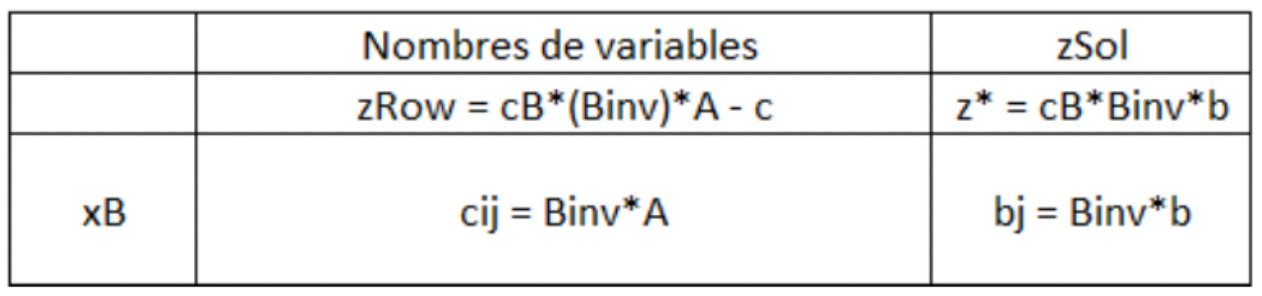

Una vez que se tiene la matriz, se realizan las operaciones necesarias para determinar qué variable entra a la base por medio de la condición de optimalidad y cuál sale con la condición de factibilidad. Así se realizan varias iteraciones hasta que se llega a la solución óptima. Para saber si ya se llegó, se debe analizar según el caso.

#### *Condición de optimalidad*

Que la variable que entra, en el caso de maximización, sea la variable no básica con el valor más negativo en los coeficientes de zRow. Si todos los valores de zRow son no negativos, se llegó al óptimo.

En el caso de minimización entra la variable más positiva y se llega al óptimo cuando todos los coeficientes de zRow son no positivos.

#### *Condición de factibilidad *

Es igual para maximización y minimización. Es cuando sale la variable básica que obtiene el valor más chico no negativo de la operación bj/cij dado que xi es la variable que entra.

En ambos casos se rompen los empates arbitrariamente.

Ahora se explica a detalle el uso de las condiciones en el caso de primal y en el dual.

#### *Simplex Primal*

Debe cumplir dos condiciones al inicio:

- Empieza con una solución factible (los valores de bj son positivos).

- No satisface la condición de optimalidad.

Después se hacen una serie de iteraciones conservando la factibilidad hasta encontrar el óptimo. Para saber qué variable entra cumpliendo con la condición de optimalidad y cuál sale según la de factibilidad, se siguen las siguientes indicaciones:

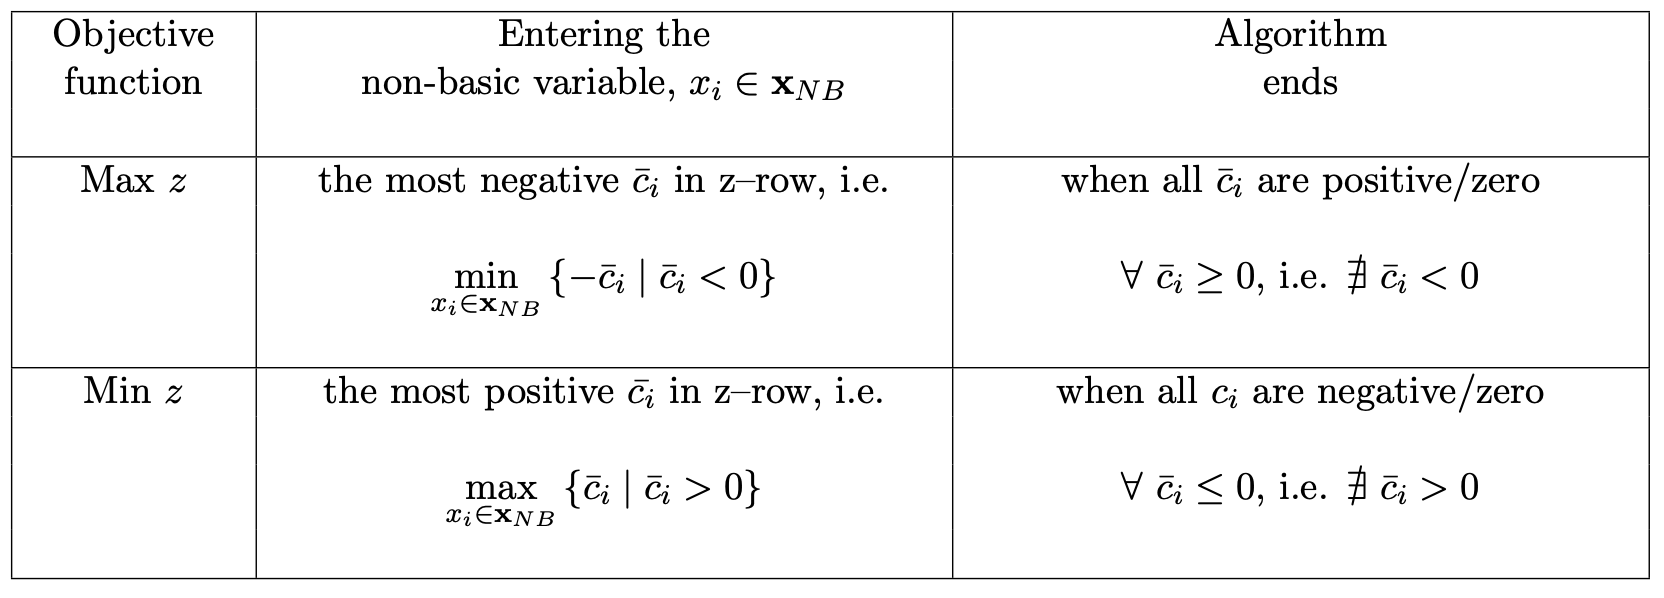

(*The Generalised Simplex Algorithm *- Luis A. Moncayo Martínez)

#### *Simplex Dual*

Debe cumplir dos condiciones al inicio:

- Que comience con una solución no factible (los valores de bj son negativos).

- Cumple con la condición de optimalidad.

Para saber qué variable entra de acuerdo con la condición de factibilidad y cuál entra según la condición de optimalidad, se siguen las siguientes indicaciones:

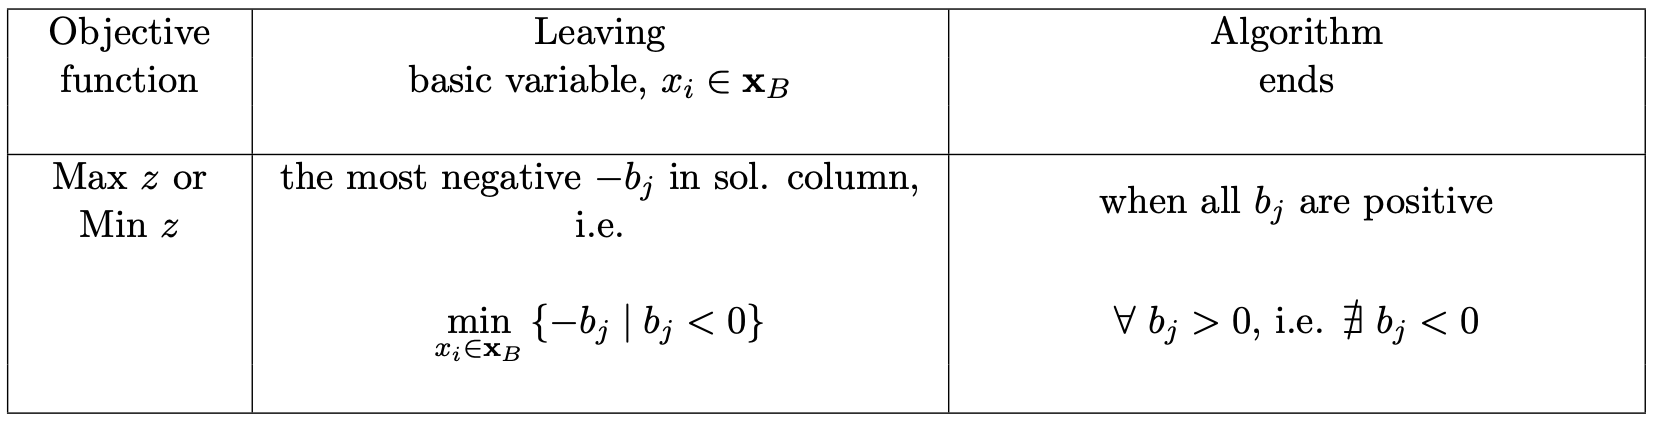

(*The Generalised Simplex Algorithm *- Luis A. Moncayo Martínez)

Al terminar las iteraciones:

- z*: Valor óptimo indicado en la matriz.

- Columna Sol: Valores óptimos de cada variable de decisión.

- z-row: Precios duales

Si una de las variables no está en la base que quedó dentro de la solución, su valor es cero.

### Implementación del modelo en el proyecto

Para este proyecto solamente se utilizaron problemas de maximización y minimización. Estos últimos pueden convertirse en unos de maximización  multiplicando la función objetivo por -1. Por lo tanto, el programa realizado puede utilizarse tanto para casos de minimización como de maximización, solamente asegurándose de que se ingresen los datos de manera adecuada.

Se utilizó el método conocido como “Big-M Method” o “Método de penalización” que se explica a continuación.

#### *Método de penalización*

Tanto en problemas de maximización como de minimización, cuando las restricciones son del tipo <= se agrega una variable de holgura (S) a la cual se le asigna el coeficiente cero en la función objetivo.

Cuando las restricciones son del tipo =, en maximización y minimización se agrega una variable artificial (A) auxiliar para los cálculos. El coeficiente que se le asigna en la función objetivo varía dependiendo del tipo de problema:

- Maximización → -M

- Minimización → M

Este coeficiente es lo que le da el nombre al método. Su trabajo es penalizar a la variable artificial para evitar que quede en el vector solución.

Cuando las restricciones son del tipo >=, se agrega una variable artificial y se le resta una variable de holgura. Para S el coeficiente en la función objetivo es cero. En el caso de la variable artificial, su coeficiente depende del tipo de problema:

- Maximización → -M

- Minimización → M

Para la función, se piden como parámetros de entrada A, b, c, x y xB. 

- A: Matriz tecnología o de coeficientes de las variables del problema en las restricciones, incluyendo variables agregadas.

- b: Vector de recursos. Son los valores a la derecha de las restricciones.

- c: Vector de coeficientes de la función objetivo, incluyendo variablesagregadas.

- x: Vector con los nombres de las variables, incluyendo las agregadas.

- xB: Conjunto básico inicial. Son los ínidices de las variables de la base inicial.

Dentro de la función, lo primero que se hace es alterar los valores recibidos para juntar en una sola variable las restricciones y la solución.

Después, se obtienen los valores faltantes para ejecutar las operaciones del algoritmo:

- B: Matriz de las columnas de A de las variables en xB.

- cB: Vector con los coeficientes de las variables de la base en la funciónobjetivo.

Se utiliza linsolve y LUP para ejecutar operaciones con la inversa de B.

El algoritmo corre mientras se cumpla la condición de que no se ha llegado al óptimo y que no se ha superado el número máximo de iteraciones.

Dentro del *while*, se verifica que la solución no sea óptima. Con eso se inicia:

- Primero se encuentra la variable que entrará de acuerdo con los criterios explicados anteriormente y se imprime su índice. 

- Después se encuentra la variable con la menor proporción entre b y la columna que sale. Esto se hace por medio de el cálculo de una proporción entre la columna de la variable que entra y la solución. 

- Después, para descartar los valores de los negativos, se usa el logaritmo.

- Una vez obtenidas las variables que se intercambiarán en la iteración, se hace la actualización de la base y de la tabla, intercambiando las variables almacenadas en los pasos explicados anteriormente. Con eso se imprime la nueva tabla.

Al salir del *while*, se verifica si la razón por la que terminó el algoritmo fue por exceso de iteraciones o porque se alcanzó la solución óptima. Dependeindo el caso, se imprime el mensaje adecuado.

Finalmente, se imprime la tabla que indica los valores óptimos de z y las variables iniciales del problema.

## PRUEBAS DEL MODELO

### Notas

Dadas las restricciones, podemos observar que cuando se tienen restricciones con desigualdades se colocan 1 para los casos de menor que (<=) y -1 para los casos de mayor que (>=) dentro de la matriz A. En la función objetivo las letras -M representando números grandes para asegurarnos que no se entre a la base. Asimismo, cuando se tiene una igualdad (=) solamente se coloca la M dentro de la función objetivo. Si fuera un problema de minimización, las M se colocarían positivas debido a que posteriormente se multiplicarían por un -1.

### Problema de Luis Antonio Moncayo: Distintos tipos de restricciones. 


$$\begin{array}{l}
\textrm{Max}\;z=2x_1 +x_2 \\
\textrm{Subject}\;\textrm{to}:\\
3x_1 +x_2 =3\\
4x_1 +3x_2 \ge 6\\
x_1 +2x_2 \le 3\\
x_1 ,x_2 \ge 0
\end{array}$$


Dadas las restricciones, podemos observar 

A = [3 1  0 0 1 0;
     4 3 -1 0 0 1;
     1 2  0 1 0 0];
b = [3;6;3];
M = 1000;
c = [2 1 0 0 -M -M];
x = {'x1', 'x2', 's2', 's3', 'A1', 'A2'};
Bx = [5 6 4];
MIN = false;

tabla = 4×7 table
     x1       x2       s2     s3    A1    A2    zSol 
    _____    _____    ____    __    __    __    _____

    -7002    -4001    1000    0     0     0     -9000
        3        1       0    0     1     0         3
        4        3      -1    0     0     1         6
        1        2       0    1     0     0         3


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 1 
La fila que sale es: 1 


tablaNueva = 4×7 table
    x1      x2        s2     s3       A1       A2    zSol 
    __    _______    ____    __    ________    __    _____

    0       -1667    1000    0         2334    0     -1998
    1     0.33333       0    0      0.33333    0         1
    0      1.6667      -1    0      -1.3333    1         2
    0      1.6667       0    1     -0.33333    0         2


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 2 
La fila que sale es: 2 


tablaNueva = 4×7 table
    x1    x2     s2     s3      A1        A2         zSol   
    __    __    ____    __    ______    ______    __________

    0     0     -0.2    0     1000.4    1000.2           2.4
    1     0      0.2    0        0.6      -0.2           0.6
    0     1     -0.6    0       -0.8       0.6           1.2
    0     0        1    1          1        -1    2.2204e-16


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 3 
La fila que sale es: 1 


tablaNueva = 4×7 table
    x1    x2    s2    s3     A1      A2     zSol
    __    __    __    __    ____    ____    ____

     1    0     0     0     1001    1000      3 
     5    0     1     0        3      -1      3 
     3    1     0     0        1       0      3 
    -5    0     0     1       -2       0     -3 


La solución actual no es óptima 
Solución no factible. Usaremos Algoritmo Dual 
La fila que sale es: 3 
La columna que entra es: 1 


tablaNueva = 4×7 table
    x1    x2    s2     s3       A1       A2        zSol   
    __    __    __    ____    ______    ____    __________

    0     0     0      0.2    1000.6    1000           2.4
    0     0     1        1         1      -1    4.4409e-16
    0     1     0      0.6      -0.2       0           1.2
    1     0     0     -0.2       0.4       0           0.6


Solución óptima encontrada 


m = 1×7 table
    x1     x2         s2        s3    A1    A2    zSol
    ___    ___    __________    __    __    __    ____

    0.6    1.2    4.4409e-16    0     0     0     2.4 


Elapsed time is 157863.808790 seconds.


m = SimplexConDual(A, c, b, x, Bx, MIN);

### Problema de Luis Antonio Moncayo: Minimización Dual.


$$\begin{array}{l}
\textrm{Min}\;z=60x_1 +{40x}_2 \\
\textrm{Subject}\;\textrm{to}:\\
5x_1 +{4x}_2 \ge 6\\
10x_1 +4x_2 \ge 8\\
x_1 ,x_2 \ge 0
\end{array}$$


A = [5 4 -1 0 1 0;
    10 4 0 -1 0 1];
b = [6;8];
M = 1000;
c = [60 40 0 0 M M];
x = {'x1', 'x2', 'S1', 'S2', 'A1', 'A2'}; 
Bx = [3 4];
MIN = true;

tabla = 3×7 table
    x1     x2    S1    S2     A1      A2     zSol
    ___    __    __    __    ____    ____    ____

     60    40    0     0     1000    1000      0 
     -5    -4    1     0       -1       0     -6 
    -10    -4    0     1        0      -1     -8 


La solución actual no es óptima 
Solución no factible. Usaremos Algoritmo Dual 
La fila que sale es: 2 
La columna que entra es: 1 


tablaNueva = 3×7 table
    x1    x2     S1     S2      A1     A2     zSol
    __    ___    __    ____    ____    ___    ____

    0      16    0        6    1000    994    -48 
    0      -2    1     -0.5      -1    0.5     -2 
    1     0.4    0     -0.1       0    0.1    0.8 


La solución actual no es óptima 
Solución no factible. Usaremos Algoritmo Dual 
La fila que sale es: 1 
La columna que entra es: 2 


tablaNueva = 3×7 table
    x1    x2     S1      S2      A1      A2      zSol
    __    __    ____    ____    ____    _____    ____

    0     0        8       2     992      998    -64 
    0     1     -0.5    0.25     0.5    -0.25      1 
    1     0      0.2    -0.2    -0.2      0.2    0.4 


Solución óptima encontrada 


m = 1×7 table
    x1     x2    S1    S2    A1    A2    zSol
    ___    __    __    __    __    __    ____

    0.4    1     0     0     0     0      64 


Elapsed time is 157864.523094 seconds.


m = SimplexConDual(A, c, b, x, Bx, MIN);

### Código del video proporcionado por Marcelo Mejía. 


$$\begin{array}{l}
\textrm{Max}\;z=5x_1 +{4x}_2 \\
\textrm{Subject}\;\textrm{to}:\\
2x_1 +x_2 \le 20\\
x_1 +x_2 \le 18\\
x_1 +2x_2 \;\ge 12\\
x_1 ,x_2 \ge 0
\end{array}$$


A = [2 1 1 0 0 0;
     1 1 0 1 0 0;
     1 2 0 0 -1 1];
b = [20;18;12];
M = 1000;
c = [5 4 0 0 0 -M];
x = {'x1','x2','S1','S2', 'S3','A3'};
Bx = [3 4 6];
MIN = false;

tabla = 4×7 table
     x1       x2      S1    S2     S3     A3     zSol 
    _____    _____    __    __    ____    __    ______

    -1005    -2004    0     0     1000    0     -12000
        2        1    1     0        0    0         20
        1        1    0     1        0    0         18
        1        2    0     0       -1    1         12


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 2 
La fila que sale es: 3 


tablaNueva = 4×7 table
    x1     x2    S1    S2     S3      A3     zSol
    ___    __    __    __    ____    ____    ____

     -3    0     0     0       -2    1002     24 
    1.5    0     1     0      0.5    -0.5     14 
    0.5    0     0     1      0.5    -0.5     12 
    0.5    1     0     0     -0.5     0.5      6 


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 1 
La fila que sale es: 1 


tablaNueva = 4×7 table
    x1    x2       S1       S2       S3          A3        zSol 
    __    __    ________    __    ________    ________    ______

    0     0            2    0           -1        1001        52
    1     0      0.66667    0      0.33333    -0.33333    9.3333
    0     0     -0.33333    1      0.33333    -0.33333    7.3333
    0     1     -0.33333    0     -0.66667     0.66667    1.3333


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 5 
La fila que sale es: 2 


tablaNueva = 4×7 table
    x1    x2    S1    S2    S3     A3     zSol
    __    __    __    __    __    ____    ____

    0     0      1     3    0     1000     74 
    1     0      1    -1    0        0      2 
    0     0     -1     3    1       -1     22 
    0     1     -1     2    0        0     16 


Solución óptima encontrada 


m = 1×7 table
    x1    x2    S1    S2    S3    A3    zSol
    __    __    __    __    __    __    ____

    2     16    0     0     22    0      74 


Elapsed time is 157864.783879 seconds.


m = SimplexConDual(A, c, b, x, Bx, MIN);

### Problema de Programación Lineal de Elaboración Propia. 


$$\begin{array}{l}
\textrm{Min}\;z=90x_1 +{55x}_2 +37x_3 \\
\textrm{Subject}\;\textrm{to}:\\
5x_1 +{4x}_2 \;+\;7x_3 \;\ge 12\\
10x_1 +{4x}_2 \;-\;x_3 \;\ge 15\\
x_1 +x_2 \;+\;x_3 \;\;\le 20\\
x_1 ,x_{2,\;} x_{3,\;} \ge 0
\end{array}$$


A = [5  4  7 -1 0  0 1  0 
     10 4 -1  0 -1 0 0  1
     1  1  1  0  0 1 0  0];
b = [12;15;20];
M = 100000;
c = [90 55 37 0 0 0 M M];
x = {'x1','x2','x3','S1','S2','S3','A1','A2'};
Bx = [3 4 5];
MIN = true;

tabla = 4×9 table
    x1     x2    x3    S1    S2    S3      A1       A2      zSol
    ___    __    __    __    __    ___    _____    _____    ____

     53    18    0     0     0     -37    1e+05    1e+05    -740
      1     1    1     0     0       1        0        0      20
      2     3    0     1     0       7       -1        0     128
    -11    -5    0     0     1      -1        0       -1     -35


La solución actual no es óptima 
Solución no factible. Usaremos Algoritmo Dual 
La fila que sale es: 3 
La columna que entra es: 2 


tablaNueva = 4×9 table
     x1     x2    x3    S1     S2      S3       A1       A2      zSol
    ____    __    __    __    ____    _____    _____    _____    ____

    13.4    0     0     0      3.6    -40.6    1e+05    99996    -866
    -1.2    0     1     0      0.2      0.8        0     -0.2      13
    -4.6    0     0     1      0.6      6.4       -1     -0.6     107
     2.2    1     0     0     -0.2      0.2        0      0.2       7


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 6 
La fila que sale es: 1 


tablaNueva = 4×9 table
     x1      x2     x3      S1     S2          S3          A1       A2       zSol  
    _____    __    _____    __    _____    ___________    _____    _____    _______

    -47.5    0     50.75    0     13.75     1.5266e-15    1e+05    99986    -206.25
     -1.5    0      1.25    0      0.25              1        0    -0.25      16.25
        5    0        -8    1        -1              0       -1        1          3
      2.5    1     -0.25    0     -0.25    -2.7756e-17        0     0.25       3.75


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 1 
La fila que sale es: 3 


tablaNueva = 4×9 table
    x1    x2      x3     S1     S2     S3     A1       A2      zSol
    __    ___    ____    __    ____    __    _____    _____    ____

    0      19      46    0        9    0     1e+05    99991    -135
    0     0.6     1.1    0      0.1    1         0     -0.1    18.5
    0      -2    -7.5    1     -0.5    0        -1      0.5    -4.5
    1     0.4    -0.1    0     -0.1    0         0      0.1     1.5


La solución actual no es óptima 
Solución no factible. Usaremos Algoritmo Dual 
La fila que sale es: 2 
La columna que entra es: 3 


tablaNueva = 4×9 table
    x1      x2       x3       S1           S2        S3       A1          A2         zSol 
    __    _______    __    _________    _________    __    ________    _________    ______

    0      6.7333    0        6.1333       5.9333    0        99994        99994    -162.6
    0     0.30667    0       0.14667     0.026667    1     -0.14667    -0.026667     17.84
    0     0.26667    1      -0.13333     0.066667    0      0.13333    -0.066667       0.6
    1     0.42667    0     -0.013333    -0.093333    0     0.013333     0.093333      1.56


Solución óptima encontrada 


m = 1×9 table
     x1     x2    x3     S1    S2     S3      A1    A2    zSol 
    ____    __    ___    __    __    _____    __    __    _____

    1.56    0     0.6    0     0     17.84    0     0     162.6


Elapsed time is 157865.103476 seconds.


m = SimplexConDual(A, c, b, x, Bx, MIN);

### Problema de David Muñoz: Tarea 1 - Ejercicio 2 (Terrazas)

Moblimex fabrica 2 tipos de muebles: 1 y 2. El mueble tipo 1 proporciona una ganancia de $25, y el tipo 2 de $30 por unidad. Las horas requeridas por cada Departamento (corte, ensamble y acabado) para cada tipo de mueble se presentan a continuación: Departamento Mueble 1 Mueble 2 Corte 1.50 3.00 Ensamble 2.00 1.00 Acabado 0.25 0.25 El Gerente de Producción estima que se tienen disponibles para este mes 450 horas de Corte, 350 de Ensamble y 50 de Acabado. Si toda la producción se puede vender, y se desea maximizar la ganancia en este mes, formule el PPL para determinar las cantidades a producir de cada tipo de mueble y calcule qué cantidades de cada tipo de mueble deben producirse y cuál sería la ganancia óptima.


$$\begin{array}{l}
\textrm{Max}\;z=25x_1 +{30x}_2 \\
\textrm{Subject}\;\textrm{to}:\\
1\ldotp 5x_1 +{3x}_2 \le 450\\
{2x}_1 +x_2 \le 350\\
{0\ldotp 25x}_1 +0\ldotp 25x_2 \;\;\le 50\\
x_1 ,x_2 \ge 0
\end{array}$$


A = [1.5   3     1  0  0 
     2     1     0  1  0
     0.25  0.25  0  0  1];
b = [450;350;50];
M = 100000;
c = [25 30 0 0 0];
x = {'x1','x2','S1','S2','S3'};
Bx = [3 4 5];
MIN = false;

tabla = 4×6 table
     x1      x2     S1    S2    S3    zSol
    ____    ____    __    __    __    ____

     -25     -30    0     0     0       0 
     1.5       3    1     0     0     450 
       2       1    0     1     0     350 
    0.25    0.25    0     0     1      50 


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 2 
La fila que sale es: 1 


tablaNueva = 4×6 table
     x1      x2       S1        S2    S3    zSol
    _____    __    _________    __    __    ____

      -10    0            10    0     0     4500
      0.5    1       0.33333    0     0      150
      1.5    0      -0.33333    1     0      200
    0.125    0     -0.083333    0     1     12.5


La solución actual no es óptima 
Solución factible. Usaremos Algoritmo Primal 
La columna que entra es: 1 
La fila que sale es: 3 


tablaNueva = 4×6 table
    x1    x2       S1       S2    S3     zSol
    __    __    ________    __    ___    ____

    0     0       3.3333    0      80    5500
    0     1      0.66667    0      -4     100
    0     0      0.66667    1     -12      50
    1     0     -0.66667    0       8     100


Solución óptima encontrada 


m = 1×6 table
    x1     x2     S1    S2    S3    zSol
    ___    ___    __    __    __    ____

    100    100    0     50    0     5500


Elapsed time is 157865.546434 seconds.


m = SimplexConDual(A, c, b, x, Bx, MIN);

## CONCLUSIONES

En el presente proyecto pudimos aprender el funcionamiento del algoritmo simplex de maximización y minimización. Dicho problema nos permitió conocer y practicar con distintas funciones y operadores en MatLab para el manejo matricial, principalmente la indexación de filas y columnas y la factorización LU. 

La programación lineal es uno de muchos métodos de la investigación de operaciones para optimizar distintos problemas. El algoritmo simplex (en cualquiera de sus variaciones, en este caso el matricial) es un método “manual” para resolver dicho problema. Sin embargo, este algoritmo suele ser el motor que está detrás de los softwares de resolución de estos problemas, tales como LINGO, LINDO, Gurobi o el Solver de Excel. 

Encontramos, gracias a este proyecto, distintas formas de programación eficiente. De entrada, omitimos utilizar la matriz inversa (que es tradicionalmente una de las operaciones del Simplex) y la sustituimos con la factorización LU.

Para resolver este problema utilizamos la ley de los grandes números, la cuál inserta variables artificiales en la función objetivo, las cuales tienen un coeficiente demasiado grande. Esto provoca que al tener restricciones del tipo “=” o “>=”, no formaran parte de la base. 

Finalmente, un reto en este proyecto fue la implementación del problema dual. Primero fue necesario estudiar las condiciones de optimalidad pues en caso contrario se debía decidir si ejecutar el problema primal o el problema dual. El problema dual parte de un vector de soluciones fuera del espacio de factibilidad y resuelve un problema “análogo” (transpuesto) al primal. Este tipo de problemas suelen aparecer cuando tenemos un problema de Minimización que parte de multiplicar la función objetivo de un problema de maximización por -1.

## REFERENCIAS

- Apuntes de la clase de Modelado y Optimización I con el professor Luis Antonio Moncayo Martínez.

- Goal Proyect. (2018, 21 de octubre). Método simplex matricial 01 [Video]. YouTube. Recuperado el 10 de marzo de 2023 de: [https://youtu.be/21lkV3r8r-4](https://youtu.be/21lkV3r8r-4)

- Moncayo, L. *The Generalized Simplex Algorithm *(documento visto en clase de Modelado y Optimización I.

## CÓDIGO

function m = SimplexConDual(A, c, b, x, Bx, MIN)
    
    %En caso de ser problema de Minimización,
    %cambiamos el signo de la función objetivo. 
    if MIN
        c = -c;
    end

    %Altero datos de entrada para obtener estructura de la matriz resultado
    %b es vector de valores restrictivos
    %Bx es conjunto básico
    A = [A, b]; %Matriz de coeficientes con restricciones
    c = [c, 0]; %Vector de coeficientes de la función objetivo
    x = [x, 'zSol'];

    %Obtener datos faltantes
    B = A(:, Bx); %Matriz con coeficientes de las restricciones solo de la base 
    % inicial.
    cB = c(Bx); %Vector de coeficientes de variables de la base en f objetivo.

    %Linsolve y LUP para obtener inv(B)*A
    [L, U, P] = lu(B);
    optsU.UT = true;
    optsL.LT = true;

    %ALin y zRow son los componentes del método tabular. 
    ALin = linsolve(U, (linsolve(L, P*A, optsL)),optsU);
    zRow = cB*ALin - c;

    %Imprimir tabla inicial
    ZCj = [zRow; ALin]; %juntamos los componentes en una sola matriz
    tabla = array2table(ZCj);%Esta única matriz es nuestra tabla del método 
    % tabular.
    tabla.Properties.VariableNames(1:size(ZCj,2)) = x %Asiganos nombres al 
    % método tabular.


    itMax = 50; %Máxima cantidad de iteraciones.
    i = 1;
    cond = true; %Do While

     %***************************************************************
     %                         ALGORITMO SIMPLEX
     %***************************************************************
    while cond && i < itMax
        i = i+1;

        %Necesitamos el vector Zrow y el Sol para evaluar optimalidad. 
        ZC = zRow(:, 1:end-1);
        sol = ALin(:, end);

        if any(sol<0) || any(ZC < 0) %Evaluamos optimalidad. 
            fprintf('La solución actual no es óptima \n');
            
            if any(sol< 0)
                %***************************************************************
                %                         D U A L
                %***************************************************************
               
                fprintf('Solución no factible. Usaremos Algoritmo Dual \n');
              
                %Encontramos la variable que sale
                [~, filaPivote] = min(sol); %El renglon es el mínimo de las 
                % soluciones
                ren = ALin(filaPivote,:);   %Ese mínimo será el renglón pivote. 
                fprintf('La fila que sale es: %d \n', filaPivote);
                 
                %Encontramos la variable que entra
                proporcion = ZC./ren(1:end-1);%Necesitamos estudiar la división 
                % de Zrow entre el pivote. 
                proporcion = log(proporcion); %Aplicamos log para facilitar la 
                % evaluación. 
                [~, colPivote] = min(proporcion); %La columna pivote será el 
                % mínimo de las divisiones. 
                fprintf('La columna que entra es: %d \n', colPivote);
               
        
            else
                %***************************************************************
                %                         P R I M A L
                %***************************************************************
                
                fprintf('Solución factible. Usaremos Algoritmo Primal \n')

                %Encontrar variable que entra
                [~, colPivote] = min(ZC); %Entra la columna que tenga el valor 
                % mínimo del Zrow
                col = ALin(:,colPivote);
                fprintf('La columna que entra es: %d \n', colPivote);
    
                %Encontrar variable que sale
                proporcion = sol./col; %Queremos evaluar la división de la 
                % solución respecto a la columna seleccionada. 
                proporcion = log(proporcion);%Facilitamos cálculo
                [~, filaPivote] = min(proporcion);%Buscamos el mínimo
                fprintf('La fila que sale es: %d \n', filaPivote);
                
            end

            %***************************************************************
            %                 ACTUALIZAR BASE Y TABLA
            %***************************************************************
            
            Bx(filaPivote) = colPivote; %La nueva base tomará el lugar de la 
            % fila que salió para darle lugar a la columna que entra. 
            B = ALin(:, Bx); %Actualizamos B según la nueva base.
            cB = c(Bx); %También actualizamos los coeficientes de la función 
            % objetivo de la base. 
            
            %Linsolve y LUP para obtener inv(B)*A
            [L, U, P] = lu(B);
            optsU.UT = true;
            optsL.LT = true;

            %ALin y zRow son los componentes del método tabular. 
            ALin = linsolve(U, (linsolve(L, P*ALin, optsL)),optsU);
            zRow = cB*ALin - c;

            %Imprimir tabla 
            ZCj = [zRow; ALin]; %juntamos los componentes en una sola matriz
            tabla = array2table(ZCj);%Esta única matriz es nuestra tabla del 
            % método tabular.
            tabla.Properties.VariableNames(1:size(ZCj,2)) = x %Asiganos 
            % nombres al método tabular.

        else
            %Si se cumple la condición de optimalidad convertiremos nuestra
            %bandera para salir de nuestro while. 
            cond = false;
        end
    end

    %Estudiamos la razón por la cuál salimos de nuestro ciclo. 
    if i >= itMax
        fprintf('Se excedió el número de iteraciones \n');
    else
        fprintf('Solución óptima encontrada \n');
    end

    %Imprimir solución final
    BaseFinal = zeros(1,size(ALin,2));
    BaseFinal(Bx) = ALin(:,end);
    BaseFinal(end) = sum(BaseFinal.*c);
    
    %En caso de ser problema de Minimización,
    %cambiamos el signo del resultado de la función objetivo. 
    if(MIN)
        BaseFinal(1, end) = -BaseFinal(1, end);
    end

    %Guaramos todo en "m" par darlo como resultado. 
    m = array2table(BaseFinal);
    m.Properties.VariableNames(1:size(m,2)) = x %; 
    toc
end
